assert(endsWith(pwd, "\defect reconstruction using coil and sensor array"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Reconstruction matrix

load('precompute_30x30x2.mat')

% lambda = 1e-9;
lambda = 1e-10;

n = size(S,2);
S_ct = pagectranspose(S);
R = pagemldivide(pagemtimes(S_ct,S) + lambda*speye(n), S_ct);

clear n lambda S S_ct

#### Perform reconstruction

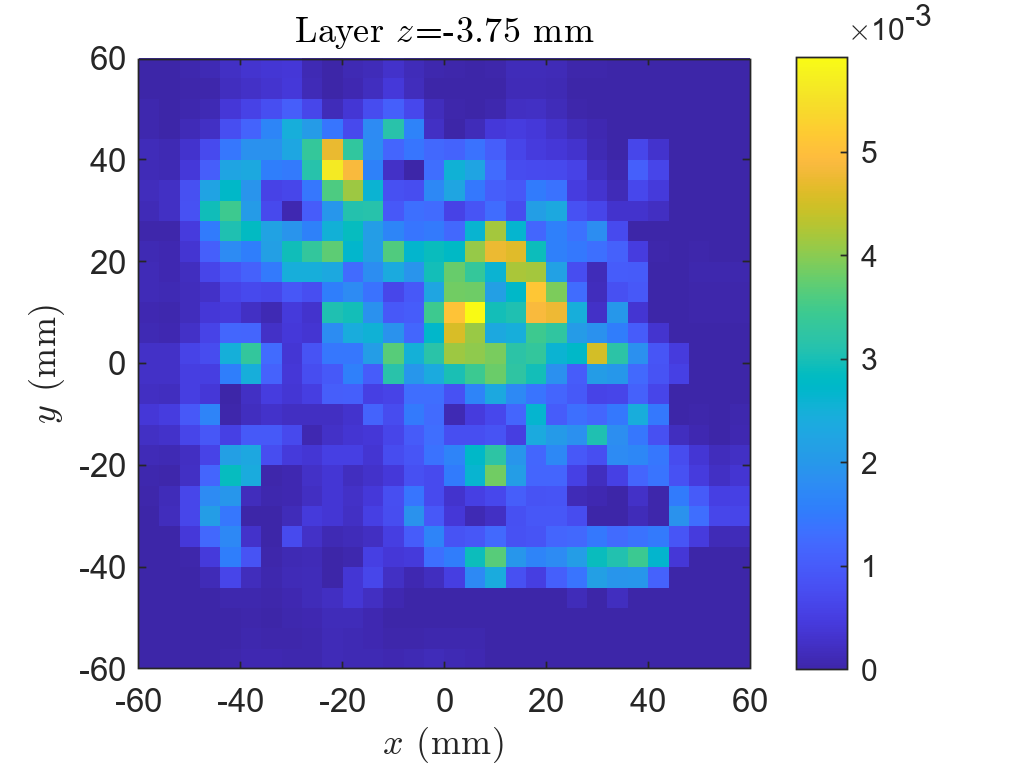

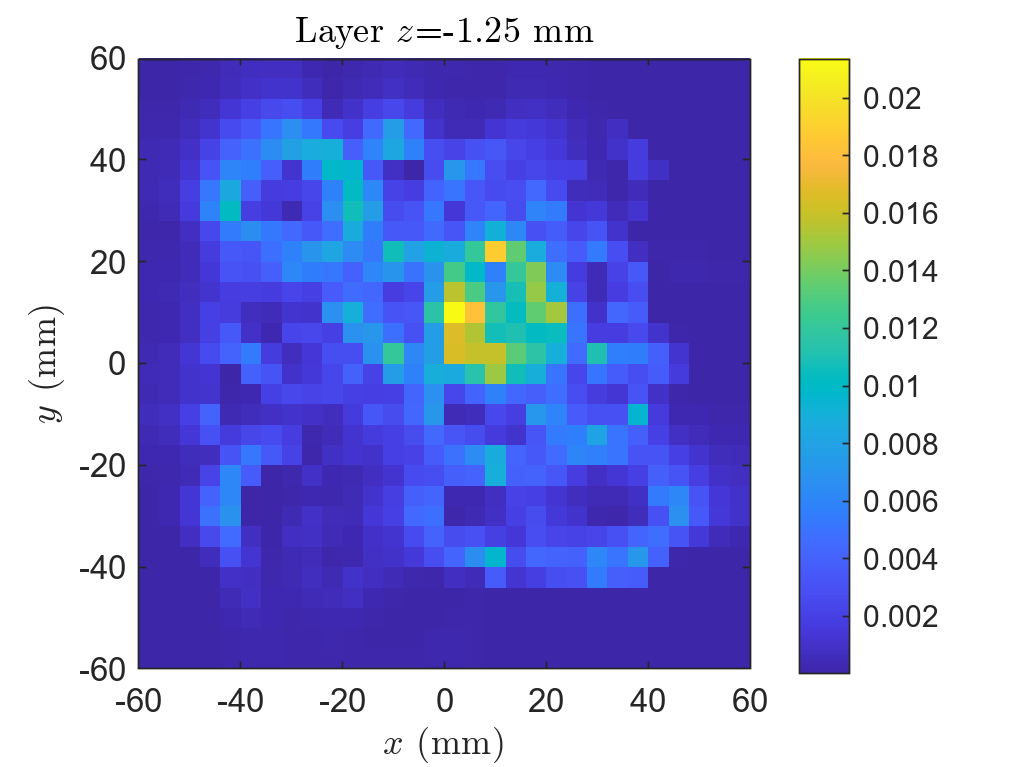

B_bar = readB('DCS_B_uniform.csv');
B_m   = readB('DCS_B_top-hole.csv');
delta_B = B_m - B_bar;
delta_p = pagemtimes(R, delta_B);

layers = unique(elems_center(3,:));
for z = layers
    mask = elems_center(3,:) == z;
    x = elems_center(1,mask) * 1e3;
    y = elems_center(2,mask) * 1e3;
    n_x = length(unique(x));
    x = reshape(x, n_x, []);
    y = reshape(y, n_x, []);

    p = delta_p(mask,:,:);
    p = max(real(p), [], 3);
    p = reshape(p, n_x, []);

    figure
    imagesc([min(x) max(x)], [min(y) max(y)], p.');
    colorbar
    title(sprintf('Layer  $z$=%.2f mm', z*1e3), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')
    xlim([-60 60])
    ylim([-60 60])
    axis xy square
end


clear layers mask n_x x y z

function B = readB(filename)

data = readmatrix(fullfile('Forward_data',filename), 'CommentStyle','%');
if contains(filename, 'DCS', 'IgnoreCase',true)
    B = permute(data, [1 3 2]);
elseif contains(filename, 'FEM', 'IgnoreCase',true)
    B = data(:, 4:end);
    num_sensors = size(B,1);
    B = reshape(B, num_sensors, 3, []);
    B = pagetranspose(B);
    B = reshape(B, num_sensors*3, 1, []);
else
    error('Unknown file formatting')
end

end